clear; clc;close all

%%1. Paramètres et chemins
path = 'E:\Data\Aurelie\data\nocues\444119\220923_plane0\';
path_tif = "E:\Data\Aurelie\data\chroms\119\exvivo.tif";
% path_csv = "E:\Data\Aurelie\data\chroms\119\220919\registration\centroid_gcamp_affine.csv";
% path_csv = "E:\Data\Aurelie\data\chroms\119\220919\registration\biapy_centroids_matched.csv";
% path_csv = "E:\Data\Aurelie\data\chroms\119\220923\registration\biapy_centroids_matched.csv";
path_csv = "E:\Data\Aurelie\data\chroms\119\220923\registration\centroid_gcamp_affinecorrected.csv";

[Volume_Utile,imgW,imgH,X_pts,Y_pts,Z_pts,NCell,num_channels,z_min_utile,z_max_utile,nb_z_utiles] = load_exvivo_image(path_tif,path_csv);

Préparation pour 305 cellules...
Chargement du TIF 3D en mémoire (cela peut prendre quelques secondes)...
Préparation : 305 cellules. Plage Z utile : 47 à 62 (16 plans).
Bloc chargé ! Dimensions : 2023 x 1968 x 16 x 4 | Z utile: 47 à 62 (16 plans)




====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 50.82 % (155 / 305 cellules correctes)



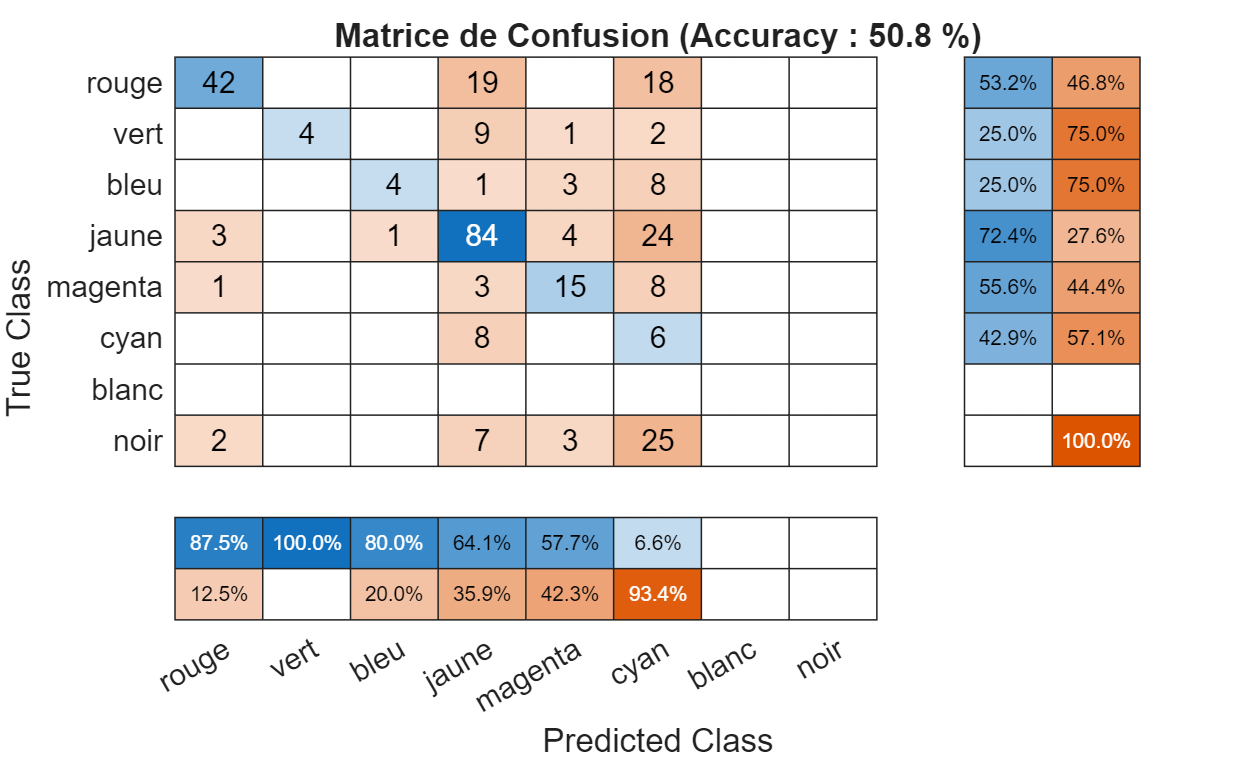

L'algorithme est en désaccord avec la Ground Truth sur 150 cellules.

Cellule | Ground Truth | Prédiction LDA | Certitude LDA (%)
----------------------------------------------------------
Cell   4 |         bleu |        magenta |   82.8 %
Cell   5 |         noir |          jaune |   75.0 %
Cell   7 |         bleu |           cyan |   99.8 %
Cell   8 |        rouge |           cyan |   96.2 %
Cell   9 |         noir |           cyan |   99.9 %
Cell  14 |         vert |          jaune |  100.0 %
Cell  16 |        rouge |           cyan |   79.5 %
Cell  23 |         noir |           cyan |  100.0 %
Cell  24 |         noir |        magenta |  100.0 %
Cell  29 |        rouge |           cyan |   99.1 %
Cell  35 |         noir |          jaune |   94.1 %
Cell  36 |         noir |          jaune |   99.7 %
Cell  38 |         vert |          jaune |  100.0 %
Cell  39 |         bleu |        magenta |  100.0 %
Cell  40 |         noir |           cyan |   99.9 %
Cell  41 |        rouge |      

radius_z = 1;
radius_xy = 2;
% [roi_red,roi_green,roi_blue,roi_ca,Coomasqx,Coomasqy] = ROI_extraction_3D_mask( ...
%     path, Volume_Utile, Z_pts, num_channels, imgW, imgH, z_min_utile, nb_z_utiles, radius_z);
% [roi_red,roi_green,roi_blue,roi_ca] = ROI_extraction_3D_centroid (Volume_Utile,X_pts,Y_pts,Z_pts,NCell,num_channels,imgW,imgH,z_min_utile,z_max_utile,nb_z_utiles,radius_z,radius_xy);
[roi_red,roi_green,roi_blue,roi_ca] = ROI_extraction_3D_centroid_sphere( ...
    Volume_Utile,X_pts,Y_pts,Z_pts,NCell,num_channels,imgW,imgH, ...
    z_min_utile,nb_z_utiles,radius_z,radius_xy);

load("E:\Data\Aurelie\data\chroms\modele_lineaire_exvivo.mat")
I = sqrt(roi_red.^2 + roi_green.^2 + roi_blue.^2);
ratio_RG = roi_red   ./ (roi_green + 0.01);
ratio_RB  = roi_red   ./ (roi_blue + 0.01);
ratio_GB  = roi_green ./ (roi_blue + 0.01);
X = [roi_red,roi_green,roi_blue,roi_ca,I,ratio_RG,ratio_RB,ratio_GB];

% Supprimer la catégorie 'noir' devenue vide (important pour confusionchart)

% --- Partition sur les données filtrées ---


classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};

% load("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_biapy_corrected_auto.mat")
test_colorcell=load("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_train200.mat");
colorcell_train=test_colorcell.colorcell;
Y_num = str2double(string(colorcell_train));
Ycat = categorical(Y_num, 1:8, classNames);
cell_IDs = [];
[certitude_max, scores, accuracy_pct, C_matrix] = test_model(MdlLin, X, Ycat, cell_IDs);

[roi_red,roi_green,roi_blue,roi_ca] = ROI_extraction_3D_centroid (Volume_Utile,X_pts,Y_pts,Z_pts,NCell,num_channels,imgW,imgH,z_min_utile,z_max_utile,nb_z_utiles);

Extraction terminée !


%[roi_red,roi_green,roi_blue,id_low_intensity] = removal_low_intensities (roi_red,roi_green,roi_blue,25,25,25);%seuil fixe et different pour red gren and blue
%id_low_intensity=[];
% [roi_green_corrected,k_estime_green] = bleedthrough_correction (roi_green,roi_ca);%add k manually
% [roi_red_corrected,k_estime_red] = bleedthrough_correction (roi_red,roi_ca);%add k manually
% [roi_blue_corrected,k_estime_blue] = bleedthrough_correction (roi_blue,roi_ca);%add k manually
% [Donnees_Clustering, r, g, b] = maxwell_proportions(roi_red_corrected,roi_green_corrected,roi_blue_corrected);
[Donnees_Clustering, r, g, b] = maxwell_proportions(roi_red,roi_green,roi_blue);
NCell = length(r);
%all=[roi_red_corrected,roi_green_corrected,roi_blue_corrected];
ep = 0; % Épaisseur de la bande noire (0.02 = environ 2% d'incertitude)
colorcell_classification = color_classification (Donnees_Clustering, NCell, r, g, b, ep);

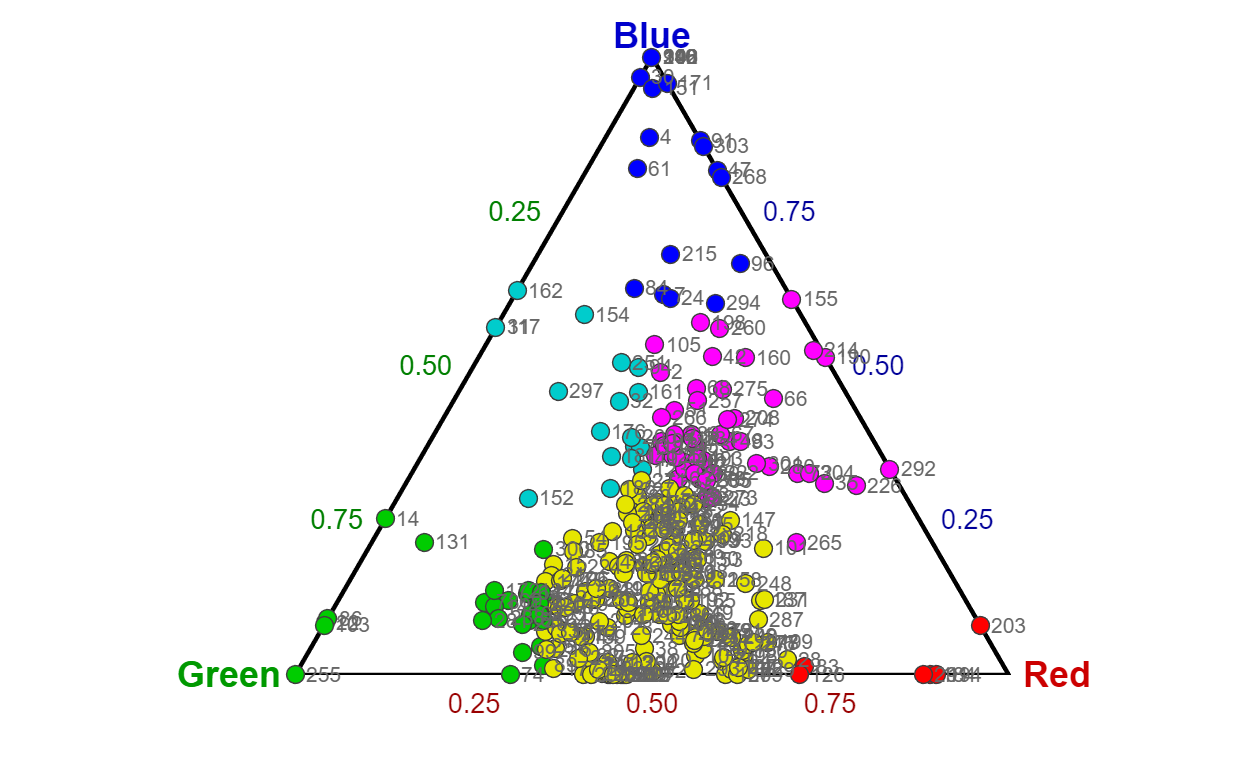

triangle_maxwell (colorcell_classification,Donnees_Clustering,1)

% load("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_biapy_raw304.mat");
% % load("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_biapy_raw.mat");
% colorcell_exvivo = colorcell;
% triangle_maxwell (colorcell_exvivo,Donnees_Clustering,1)

% 
% colorcell=colorcell_classification;

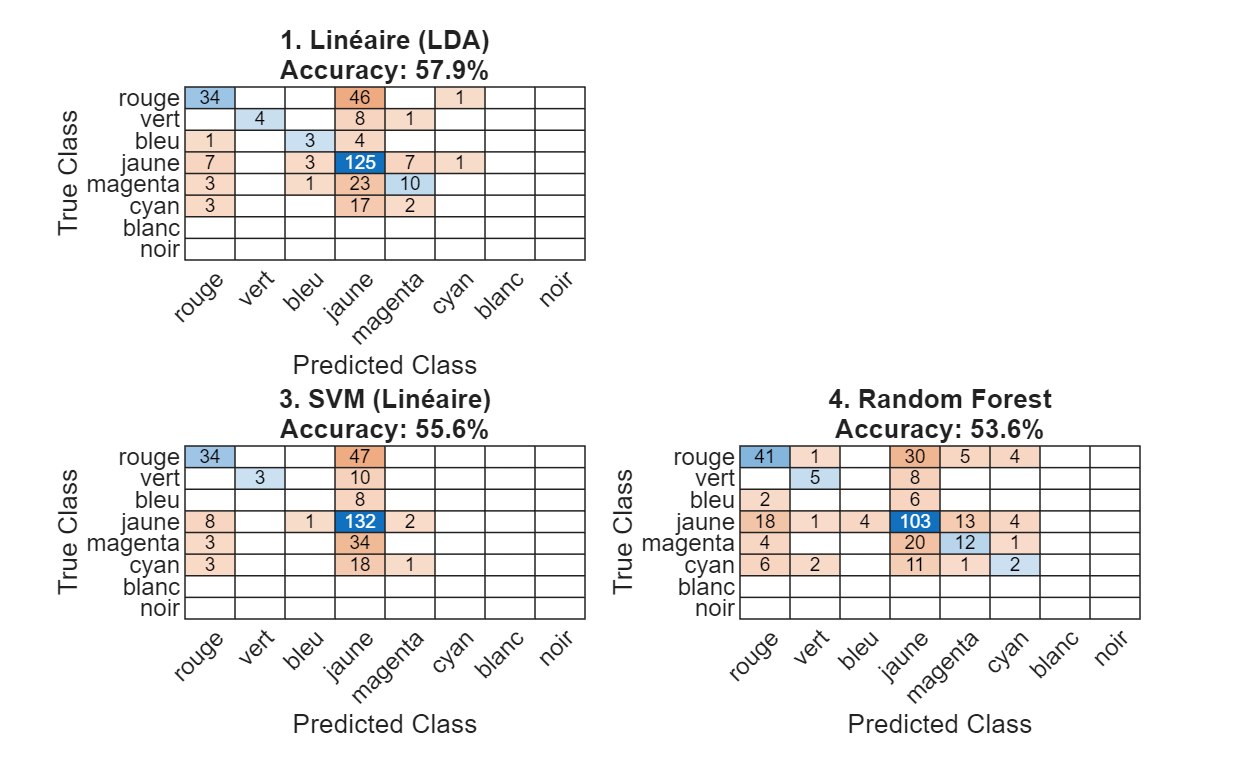


====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 57.89 %
3. SVM Multi-classes    : 55.59 %
4. Random Forest        : 53.62 %


load("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_biapy_raw304.mat");
colorcell_exvivo = colorcell;
[ MdlLin, MdlSVM, MdlRF,X,Ycat, cell_IDs] = prediction_color(colorcell_exvivo,roi_red,roi_green,roi_blue,roi_ca);

Accord global entre les deux méthodes : 29.84%
Accuracy sur les neurones actifs (sans Black) : 42.33%


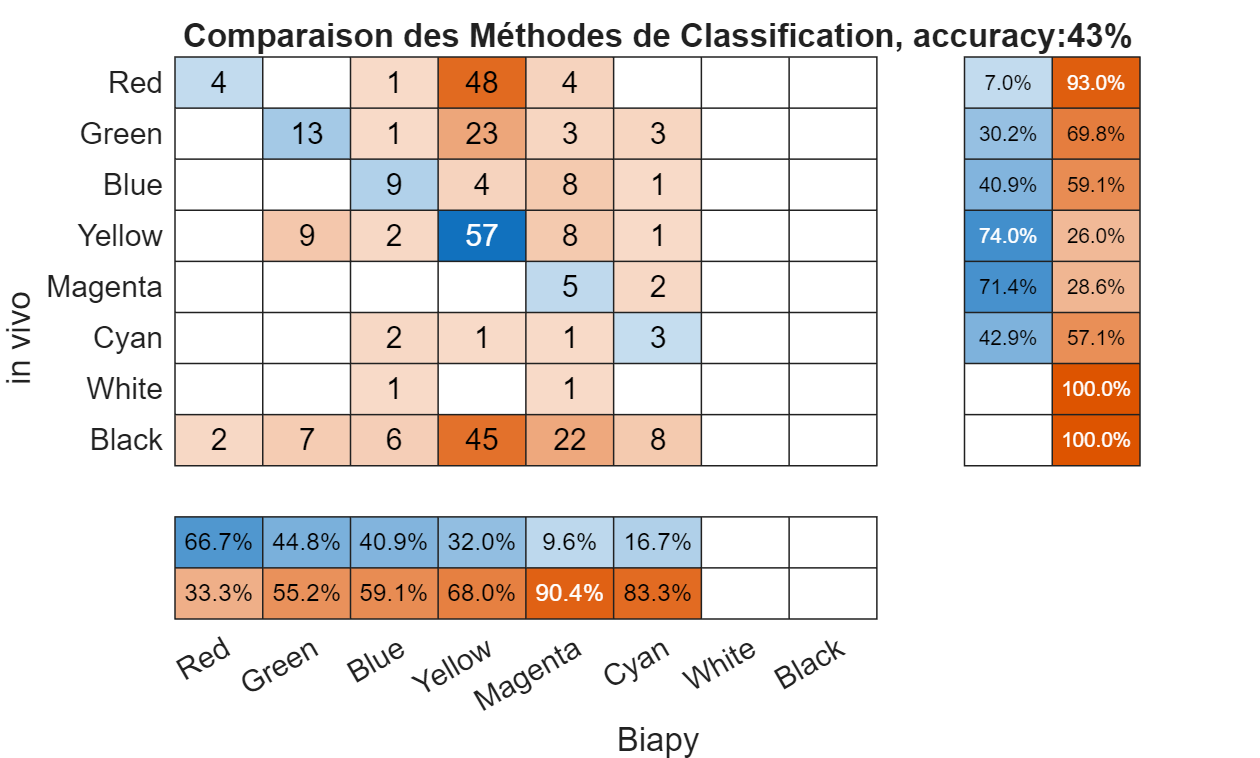

% save ("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_exvivoJC","colorcell")
%colorcell = distance_control(colorcell);
%consensus matrix
% load("E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_invivo_20260424.mat");

colorcell_method2 = uint8(colorcell_classification);
% load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcellnew.mat");
load("E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcellnew.mat");
colorcell_method1 = uint8(colorcell);
write_number=1; %write_number on maxwell triangle
confusion_matrix (colorcell_method1,colorcell_method2);

return


function [Volume_Utile,imgW,imgH,X_pts,Y_pts,Z_pts,NCell,num_channels,z_min_utile,z_max_utile,nb_z_utiles] = load_exvivo_image(path_tif,path_csv)

radius = 2;   % Demi-fenêtre en X,Y (patch 5x5)
radius_z = 1; % Demi-fenêtre en Z (volume Z-1, Z, Z+1)

% L'ordre de ton TIF (Très important pour le chargement)
ordre_tif = 'ChannelsFirst'; % Ou 'ZFirst' selon ImageJ
num_channels = 4; % Rouge,Vert,Bleu, Calcium

%% 2. Lecture du CSV
coords = readtable(path_csv);
coords = coords(2:end,:);
Z_pts = round(coords{:, 1}); % Prend toutes les lignes de la 1ère colonne
X_pts = round(coords{:, 3}); % Prend toutes les lignes de la 2ème colonne
Y_pts = round(coords{:, 2}); % Prend toutes les lignes de la 3ème colonne

NCell = height(coords);

fprintf('Préparation pour %d cellules...\n', NCell);

%% 3. CHARGEMENT COMPLET DU VOLUME 3D EN RAM
fprintf('Chargement du TIF 3D en mémoire (cela peut prendre quelques secondes)...\n');
info = imfinfo(path_tif);
total_pages = numel(info);
num_Z = total_pages / num_channels;

z_min_utile = max(1, min(Z_pts) - radius_z); % Ex: 36 - 1 = 35
z_max_utile = max(Z_pts) + radius_z;         % Ex: 81 + 1 = 82
nb_z_utiles = z_max_utile - z_min_utile + 1;

fprintf('Préparation : %d cellules. Plage Z utile : %d à %d (%d plans).\n', ...
    NCell, z_min_utile, z_max_utile, nb_z_utiles);

info = imfinfo(path_tif);
imgW = info(1).Width;
imgH = info(1).Height;

% Volume_Utile = zeros(imgH, imgW, nb_z_utiles, num_channels, 'double');
Volume_Utile = zeros(imgH, imgW, nb_z_utiles, num_channels, 'uint16');
%hWait = waitbar(0, 'Chargement des images TIF en cours...', 'Name', 'Lecture 3D');

% Calcul du nombre total d'itérations pour la barre de progression
total_iterations = nb_z_utiles * num_channels;
compteur = 0;

% On boucle uniquement sur les plans Z dont on a besoin
for z = z_min_utile : z_max_utile
    
    % Pour ce plan Z, on charge les 4 couleurs
    for c = 1:num_channels
        
        % Formule pour trouver la page dans le gros TIF
        if strcmp(ordre_tif, 'ChannelsFirst')
            page = (z - 1) * num_channels + c;
        else
            total_Z_tif = numel(info) / num_channels;
            page = (c - 1) * total_Z_tif + z;
        end
        
        % On calcule l'indice de stockage dans notre "petit" Volume_Utile
        % Ex: Si z_min_utile = 35, le plan Z=35 ira dans la case z_idx = 1
        z_idx = z - z_min_utile + 1; 
        
        Volume_Utile(:, :, z_idx, c) = double(imread(path_tif, 'Index', page));
               % --- MISE À JOUR DE LA BARRE DE PROGRESSION ---
        % compteur = compteur + 1;
        % % On calcule le pourcentage (entre 0 et 1)
        % progression = compteur / total_iterations;
        % 
        % % On met à jour la barre et le texte (tous les 4 plans Z pour ne pas ralentir le code)
        % if mod(compteur, 4) == 0 || compteur == total_iterations
        %     waitbar(progression, hWait, sprintf('Chargement : %d %% (%d / %d images)', ...
        %         round(progression * 100), compteur, total_iterations));
        % end
    end
end
fprintf('Bloc chargé ! Dimensions : %d x %d x %d x %d | Z utile: %d à %d (%d plans)\n', ...
    imgH, imgW, nb_z_utiles, num_channels, z_min_utile, z_max_utile, nb_z_utiles);
%close(hWait)

end

% function [R,G,B,Cal] = ROI_extraction_3D_centroid (Volume_Utile,X_pts,Y_pts,Z_pts,NCell,num_channels,imgW,imgH,z_min_utile,z_max_utile,nb_z_utiles,radius_z,radius)
% 
% %% 4. EXTRACTION DES INTENSITÉS
% intensity_features = zeros(NCell, num_channels);
% % radius = 1;   % Demi-fenêtre en X,Y (patch 5x5)
% % radius_z = 1; % Demi-fenêtre en Z (volume Z-1, Z, Z+1)
% for n = 1:NCell
%     cx = X_pts(n);
%     cy = Y_pts(n);
%     cz = Z_pts(n);
% 
%     % Bords X,Y
%     col_min = max(1, cx - radius);
%     col_max = min(imgW, cx + radius);
%     row_min = max(1, cy - radius);
%     row_max = min(imgH, cy + radius);
% 
%     % --- ADAPTATION DES BORD Z ---
%     % cz est la coordonnée ABSOLUE (ex: 36).
%     % Il faut la convertir en coordonnée RELATIVE à notre Volume_Utile (ex: 2)
%     cz_relatif = cz - z_min_utile + 1;
% 
%     z_min_rel = max(1, cz_relatif - radius_z);
%     z_max_rel = min(nb_z_utiles, cz_relatif + radius_z);
% 
%     % Extraction et moyenne
%     for c = 1:num_channels
%         patch_3D = Volume_Utile(row_min:row_max, col_min:col_max, z_min_rel:z_max_rel, c);
%         intensity_features(n, c) = median(double(patch_3D(:)));
%         % intensity_features(n, c) = mean(patch_3D(:));
%     end
% end
% 
% fprintf('Extraction terminée !\n');
% 
% % %% 5. Normalisation
% X_base = intensity_features;
% X_norm = normalize(X_base, 'range');
% 
% R = X_norm(:, 1);
% G = X_norm(:, 2);
% B = X_norm(:, 3);
% Cal = X_norm(:, 4);
% 
% % R = intensity_features(:, 1);
% % G = intensity_features(:, 2);
% % B = intensity_features(:, 3);
% % Cal = intensity_features(:, 4);
% 
% end

function [R,G,B,Cal] = ROI_extraction_3D_centroid_sphere( ...
    Volume_Utile,X_pts,Y_pts,Z_pts,NCell,num_channels,imgW,imgH, ...
    z_min_utile,nb_z_utiles,radius_z,radius_xy)

intensity_features = zeros(NCell, num_channels);

for n = 1:NCell
    cx = X_pts(n);
    cy = Y_pts(n);
    cz = Z_pts(n);

    col_min = max(1, cx - radius_xy);
    col_max = min(imgW, cx + radius_xy);
    row_min = max(1, cy - radius_xy);
    row_max = min(imgH, cy + radius_xy);

    cz_relatif = cz - z_min_utile + 1;
    z_min_rel = max(1, cz_relatif - radius_z);
    z_max_rel = min(nb_z_utiles, cz_relatif + radius_z);

    nx = col_max - col_min + 1;
    ny = row_max - row_min + 1;
    nz = z_max_rel - z_min_rel + 1;

    [Xg,Yg,Zg] = meshgrid(col_min:col_max, row_min:row_max, z_min_rel:z_max_rel);

    mask_sphere = ((Xg - cx).^2 / radius_xy^2) + ...
                  ((Yg - cy).^2 / radius_xy^2) + ...
                  ((Zg - cz_relatif).^2 / radius_z^2) <= 1;

    for c = 1:num_channels
        patch_3D = double(Volume_Utile(row_min:row_max, col_min:col_max, z_min_rel:z_max_rel, c));
        vals = patch_3D(mask_sphere);
        intensity_features(n,c) = median(vals(:), 'omitnan');
    end
end

X_norm = normalize(intensity_features, 'range');
R = X_norm(:,1);
G = X_norm(:,2);
B = X_norm(:,3);
Cal = X_norm(:,4);
end

function [R,G,B,Cal,Coomasqx,Coomasqy] = ROI_extraction_3D_mask( ...
    path, Volume_Utile, Z_pts, num_channels, imgW, imgH, z_min_utile, nb_z_utiles, radius_z)

load(fullfile(path, 'Fall.mat'),'stat','iscell');

se = strel('disk', 1);

NCell_total = sum(iscell(:,1) > 0);
R   = zeros(NCell_total,1);
G   = zeros(NCell_total,1);
B   = zeros(NCell_total,1);
Cal = zeros(NCell_total,1);

Coomasqx = cell(1, NCell_total);
Coomasqy = cell(1, NCell_total);

m = 0;

for n = 1:length(stat)
    if iscell(n,1) == 1
        m = m + 1;

        xpix = double(stat{1,n}.xpix) + 1;
        ypix = double(stat{1,n}.ypix) + 1;

        xpix = max(1, min(xpix, imgW));
        ypix = max(1, min(ypix, imgH));

        lin_idx = sub2ind([imgH, imgW], ypix, xpix);

        mask = false(imgH, imgW);
        mask(lin_idx) = true;
        mask_eroded = imerode(mask, se);

        eroded_idx_2D = find(mask_eroded);
        if isempty(eroded_idx_2D)
            eroded_idx_2D = lin_idx;
        end

        [new_y, new_x] = ind2sub([imgH, imgW], eroded_idx_2D);
        Coomasqx{m} = new_x;
        Coomasqy{m} = new_y;

        cz = Z_pts(m);
        cz_rel = cz - z_min_utile + 1;

        z_min_rel = max(1, cz_rel - radius_z);
        z_max_rel = min(nb_z_utiles, cz_rel + radius_z);

        valsR = [];
        valsG = [];
        valsB = [];
        valsC = [];

        for z = z_min_rel:z_max_rel
            sliceR = Volume_Utile(:,:,z,1);
            sliceG = Volume_Utile(:,:,z,2);
            sliceB = Volume_Utile(:,:,z,3);
            sliceC = Volume_Utile(:,:,z,4);

            valsR = [valsR; double(sliceR(eroded_idx_2D))];
            valsG = [valsG; double(sliceG(eroded_idx_2D))];
            valsB = [valsB; double(sliceB(eroded_idx_2D))];
            valsC = [valsC; double(sliceC(eroded_idx_2D))];
        end

        % R(m)   = median(valsR);
        % 
        % G(m)   = median(valsG);
        % B(m)   = median(valsB);
        % Cal(m) = median(valsC);
        R(m) = median(valsR(:),'omitnan');
        G(m) = median(valsG(:),'omitnan');
        B(m) = median(valsB(:),'omitnan');
        Cal(m) = median(valsC(:),'omitnan');
    end
end

R   = R(1:m);
G   = G(1:m);
B   = B(1:m);
Cal = Cal(1:m);

end

%% 3.5 VISUALISATION INTERACTIVE DU VOLUME ET DES CELLULES
% Ce bloc ouvre une fenêtre pour vérifier que le CSV est bien aligné avec le TIF

% Choix du canal à afficher (Ex: 3 pour le Vert, 4 pour le Calcium)
canal_affichage = 3; 

% On crée une nouvelle figure pour notre interface
fig_verif = figure('Name', 'Vérification de l''alignement TIF / CSV', ...
                   'NumberTitle', 'off', 'Position', [100, 100, 800, 800]);

% Création des axes pour l'image
ax = axes('Parent', fig_verif, 'Position', [0.1, 0.2, 0.8, 0.7]);

% --- ÉLÉMENTS DE CONTRÔLE (Slider et Checkbox) ---
% 1. Le slider pour changer le plan Z
slider_z = uicontrol('Parent', fig_verif, 'Style', 'slider', ...
                     'Position', [100, 50, 600, 20], ...
                     'Min', 1, 'Max', nb_z_utiles, ...
                     'Value', round(nb_z_utiles/2), ... % On commence au milieu
                     'SliderStep', [1/max(1, nb_z_utiles-1), 10/max(1, nb_z_utiles-1)]);

% 2. Le texte qui indique le Z actuel
txt_z = uicontrol('Parent', fig_verif, 'Style', 'text', ...
                  'Position', [350, 20, 100, 20], ...
                  'String', sprintf('Plan Z : %d', z_min_utile + round(nb_z_utiles/2) - 1));

% 3. La case à cocher pour afficher les cellules
check_cellules = uicontrol('Parent', fig_verif, 'Style', 'checkbox', ...
                           'Position', [100, 80, 200, 20], ...
                           'String', 'Afficher les cellules (CSV)', ...
                           'Value', 1); % Cochée par défaut

% Stockage des données dans la figure pour y accéder depuis la fonction callback
guidata(fig_verif, struct('Volume', Volume_Utile, 'X', X_pts, 'Y', Y_pts, ...
                          'Z', Z_pts, 'Zmin', z_min_utile, 'Ax', ax, ...
                          'Txt', txt_z, 'Check', check_cellules, 'Canal', canal_affichage, 'Radius', radius));

% Définition de la fonction qui s'exécute quand on touche au slider ou à la checkbox
set(slider_z, 'Callback', @update_image);
set(check_cellules, 'Callback', @update_image);

% Affichage initial
update_image(slider_z, []);

disp('Mettez en pause le script ou fermez la figure pour continuer l''extraction...');
%uiwait(fig_verif); % Le code s'arrête ici tant que tu n'as pas fermé la fenêtre !


%% --- FONCTION DE MISE À JOUR DE L'IMAGE (À copier TOUT À LA FIN de ton script) ---
%% --- FONCTION DE MISE À JOUR DE L'IMAGE EN COULEUR ---
function update_image(hObject, ~)
    % Récupération des données stockées dans la figure
    data = guidata(hObject);
    
    % Récupération du Z actuel
    z_relatif = round(get(findobj(hObject.Parent, 'Style', 'slider'), 'Value'));
    z_absolu = data.Zmin + z_relatif - 1;
    
    % Mise à jour du texte
    set(data.Txt, 'String', sprintf('Plan Z : %d', z_absolu));
    
    % --- CRÉATION DE L'IMAGE COMPOSITE RGB ---
    % On extrait les 3 canaux correspondant aux couleurs (Bleu=1, Rouge=2, Vert=3)
    % Ajuste les indices si l'ordre de ton microscope est différent !
    img_Bleu  = data.Volume(:, :, z_relatif, 1); 
    img_Rouge = data.Volume(:, :, z_relatif, 2);
    img_Vert  = data.Volume(:, :, z_relatif, 3);
    
    % Normalisation de chaque canal entre 0 et 1 pour l'affichage
    % On utilise imadjust ou simplement une division par le max local
    max_B = max(img_Bleu(:));  if max_B == 0, max_B = 1; end
    max_R = max(img_Rouge(:)); if max_R == 0, max_R = 1; end
    max_V = max(img_Vert(:));  if max_V == 0, max_V = 1; end
    
    % On booste un peu le contraste (multiplier par 1.5) pour bien voir les fluos
    canal_R = min(1, (img_Rouge / max_R) * 1.5);
    canal_V = min(1, (img_Vert / max_V) * 1.5);
    canal_B = min(1, (img_Bleu / max_B) * 1.5);
    
    % On assemble les 3 matrices en un cube (H x W x 3) que MATLAB comprend comme une image RGB
    img_RGB = cat(3, canal_R, canal_V, canal_B);
    
    % Affichage de la belle image en couleur !
    imshow(img_RGB, 'Parent', data.Ax);
    hold(data.Ax, 'on');
    
    % --- AFFICHAGE DES CELLULES ---
    if get(data.Check, 'Value') == 1
        % On cherche les cellules qui se trouvent sur ce plan Z précis
        idx_z = find(data.Z == z_absolu);
        
        if ~isempty(idx_z)
            % On trace des cercles BLANCS autour des centroïdes pour bien les voir sur les couleurs
            viscircles(data.Ax, [data.X(idx_z), data.Y(idx_z)], ...
                       repmat(data.Radius, length(idx_z), 1), ...
                       'Color', 'w', 'LineWidth', 1.0);
            
            % Écrire le numéro de la cellule (en jaune pour ressortir)
            for k = 1:length(idx_z)
                text(data.Ax, data.X(idx_z(k)) + 5, data.Y(idx_z(k)), ...
                     num2str(idx_z(k)), 'Color', 'y', 'FontSize', 8, 'FontWeight', 'bold');
            end
        end
    end
    hold(data.Ax, 'off');
end

% On rassemble les vraies coordonnées d'origine et la couleur ground truth
Table_Cellules = table((1:length(X_tri))', X_pts, Y_pts, Z_pts, Ycat, ...
    'VariableNames', {'ID_Cellule', 'X', 'Y', 'Z', 'Couleur_CSV'});

% Ouvre le tableau dans une fenêtre interactive MATLAB (très pratique pour chercher)
% openvar('Table_Cellules');
return

figure
gscatter(X_base(:,1), X_base(:,2), Ycat, couleurs_affichage, '.', 15);
title ('red/green')
legend off
xlabel('red');
ylabel('green');

figure
gscatter(X_base(:,1), X_base(:,3), Ycat, couleurs_affichage, '.', 15);
title ('red/blue')
legend off
xlabel('red');
ylabel('blue');

figure
gscatter(X_base(:,2), X_base(:,3), Ycat, couleurs_affichage, '.', 15);
title ('green/blue')
legend off
xlabel('green');
ylabel('blue');

scatter3(X_base(:,1), X_base(:,2), X_base(:,3), 64, double(Ycat), 'filled');
colormap(couleurs_affichage);
caxis([1 8]);
xlabel('red');
ylabel('green');
zlabel('blue');


classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

couleurs_affichage = [
    1.0 0.0 0.0;   % rouge
    0.0 0.8 0.0;   % vert
    0.0 0.0 1.0;   % bleu
    0.9 0.9 0.0;   % jaune
    1.0 0.0 1.0;   % magenta
    0.0 0.8 0.8;   % cyan
    0.6 0.6 0.6;   % blanc/gris
    0.0 0.0 0.0    % noir
];

figure('Color','w');
hold on;
grid on;

for k = 1:8
    idx = (Y_num == k);
    scatter3(X_base(idx,1), X_base(idx,2), X_base(idx,3), ...
        15, couleurs_affichage(k,:), 'filled');
end

title('Graphique 3D');
xlabel('green');
ylabel('blue');
zlabel('3e variable');
legend off;
axis vis3d;
view(35,25);

videoFile = fullfile('E:', 'rotation_graph_3d.mp4');
v = VideoWriter(videoFile, 'MPEG-4');
v.FrameRate = 20;
v.Quality = 100;
open(v);

for az = 1:2:360
    view(az, 25);
    drawnow;
    frame = getframe(gcf);
    writeVideo(v, frame);
end

close(v);


function colorecell = distance_control(colorcell)

% path = 'E:\Data\Aurelie\data\chroms\119\220923\registration\';
% path = "E:\Data\Aurelie\data\chroms\119\220919\registration_results_plan1_220919\";
path = "E:\Data\Aurelie\data\chroms\582\230331plane0\";
% path = "E:\Data\Aurelie\data\chroms\582\230331plane0\";
path_biapy = strcat(path,'biapy_centroids_matched.csv');
path_gcamp = strcat(path,'centroid_gcamp_affine.csv');
%load("E:\Data\Aurelie\data\chroms\582\230331plane0\colorcell_biapy_raw.mat");

% === Calcul de la distance 3D entre centroides biapy et gcamp ===

% Chargement des CSV (skip de la ligne 1 = header)
biapy  = readmatrix(path_biapy,   'NumHeaderLines', 1);
gcamp  = readmatrix(path_gcamp,        'NumHeaderLines', 1);

% Colonnes : 1=Z, 2=X, 3=Y
z_b = biapy(:,1);  x_b = biapy(:,2);  y_b = biapy(:,3);
z_g = gcamp(:,1);  x_g = gcamp(:,2);  y_g = gcamp(:,3);

% Distance euclidienne 3D pour chaque cellule
distances = sqrt((x_b - x_g).^2 + (y_b - y_g).^2 + (z_b - z_g).^2);

% Affichage
n = numel(distances);
fprintf('Nombre de cellules : %d\n', n);
fprintf('Distance moyenne   : %.4f\n', mean(distances));
fprintf('Distance min       : %.4f\n', min(distances));
fprintf('Distance max       : %.4f\n', max(distances));

% Export CSV résultat
cell_idx = (1:n)';
T = table(cell_idx, z_b, x_b, y_b, z_g, x_g, y_g, distances, ...
    'VariableNames', {'cellule','Z_biapy','X_biapy','Y_biapy', ...
                      'Z_gcamp','X_gcamp','Y_gcamp','distance_3D'});
writetable(T, 'distances_biapy_gcamp.csv');
fprintf('Résultat exporté dans distances_biapy_gcamp.csv\n');

histogram(distances,25);

indices_sup = find(distances > 8);

fprintf('Nombre de cellules avec distance > 8 : %d\n', numel(indices_sup));
disp('Indices :');
indices_sup

% Affichage détaillé avec les distances correspondantes
fprintf('\nCellule\tDistance\n');
for k = 1:numel(indices_sup)
    fprintf('%d\t\t%.4f\n', indices_sup(k), distances(indices_sup(k)));
end
liste_binaire = double(distances < 8);
colorcell(liste_binaire==0) = 8;
% Distance euclidienne 2D pour chaque cellule

distances = sqrt((x_b - x_g).^2 + (y_b - y_g).^2 );

% Affichage
n = numel(distances);
fprintf('Nombre de cellules : %d\n', n);
fprintf('Distance moyenne   : %.4f\n', mean(distances));
fprintf('Distance min       : %.4f\n', min(distances));
fprintf('Distance max       : %.4f\n', max(distances));

% Export CSV résultat
cell_idx = (1:n)';
T = table(cell_idx, z_b, x_b, y_b, z_g, x_g, y_g, distances, ...
    'VariableNames', {'cellule','Z_biapy','X_biapy','Y_biapy', ...
                      'Z_gcamp','X_gcamp','Y_gcamp','distance_3D'});
writetable(T, 'distances_biapy_gcamp.csv');
fprintf('Résultat exporté dans distances_biapy_gcamp.csv\n');

histogram(distances,15);

indices_supxy = find(distances > 4);

fprintf('Nombre de cellules avec distance > 10 : %d\n', numel(indices_supxy));
disp('Indices :');
disp(indices_supxy);

% Affichage détaillé avec les distances correspondantes
fprintf('\nCellule\tDistance\n');
for k = 1:numel(indices_supxy)
    fprintf('%d\t\t%.4f\n', indices_supxy(k), distances(indices_supxy(k)));
end
liste_binairexy = double(distances < 4);

colorcell(liste_binaire==0) = 8;
% save (strcat(path,'colorcell_biapy_distance'),'colorcell')
% disp('saved colorcell')

end

function [MdlLin,  MdlSVM, MdlRF,X,Ycat, cell_IDs] = prediction_color(colorcell,roi_red,roi_green,roi_blue,roi_ca,roi_green_corrected)

if nargin==4
    X = [roi_red, roi_green,roi_blue];
elseif nargin==5
    X = [roi_red, roi_green,roi_blue,roi_ca];
elseif nargin==6
    X = [roi_red, roi_green,roi_blue,roi_green_corrected,roi_ca];
end

I = sqrt(roi_red.^2 + roi_green.^2 + roi_blue.^2);

% rouge_brut_z = zscore(roi_red_raw);
% vert_brut_z  = zscore(roi_green_raw);
% bleu_brut_z  = zscore(roi_blue_raw);
% X = [I_blue, I_red, I_green, I_calcium, I_green_dec];
ratio_RG = roi_red   ./ (roi_green + 0.01);
ratio_RB  = roi_red   ./ (roi_blue + 0.01);
ratio_GB  = roi_green ./ (roi_blue + 0.01);
X = [X,I,ratio_RG,ratio_RB,ratio_GB];

% Supprimer la catégorie 'noir' devenue vide (important pour confusionchart)

% --- Partition sur les données filtrées ---

rng(1);
K = 10;

Y_num = str2double(string(colorcell));

% On recrée la variable catégorielle proprement avec les 8 couleurs
classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

cell_IDs_original = (1:length(Ycat))';

maskNoNoir = Ycat ~= 'noir';   % vecteur logique : true pour toutes les classes sauf noir
% mask_noir   = (Ycat == 'noir');
% mask_actifs = ~mask_noir;   % toutes les classes sauf noir
X_filt   = X(maskNoNoir, :);   % features filtrées
X = X_filt;

Ycat = Ycat(maskNoNoir);  % labels filtrés
cell_IDs = cell_IDs_original(maskNoNoir);
% cell_IDs = cell_IDs_original;
mask_valide = ~any(isnan(X), 2) & ~any(isinf(X), 2);
% 
% On ne garde que les cellules valides
X = X(mask_valide, :);
Ycat = Ycat(mask_valide);
cell_IDs = cell_IDs(mask_valide);

% Création de la partition stratifiée
cvp = cvpartition(Ycat, 'KFold', K);


%% ================= 1. MODÈLE LINÉAIRE (LDA) =================
CVMdlLin = fitcdiscr(X, Ycat, 'DiscrimType', 'linear', 'CVPartition', cvp);
accLin = 1 - kfoldLoss(CVMdlLin);
YPredLin = kfoldPredict(CVMdlLin);
% Accuracy sans les noirs


subplot(2, 2, 1);
confusionchart(Ycat, YPredLin, 'Title', sprintf('1. Linéaire (LDA)\nAccuracy: %.1f%%', accLin*100));

% %% ================= 2. MODÈLE QUADRATIQUE (QDA) =================
% % Attention: La QDA peut planter si une classe a trop peu de points par rapport
% % au nombre de variables. MATLAB mettra un 'pseudoLinear' si besoin.
% CVMdlQuad = fitcdiscr(X, Ycat, 'DiscrimType', 'quadratic', 'CVPartition', cvp);
% accQuad = 1 - kfoldLoss(CVMdlQuad);
% YPredQuad = kfoldPredict(CVMdlQuad);
% % Accuracy sans les noirs

% 
% subplot(2, 2, 2);
% confusionchart(Ycat, YPredQuad, 'Title', sprintf('2. Quadratique (QDA)\nAccuracy: %.1f%%', accQuad*100));

%% ================= 3. MODÈLE SVM (Support Vector Machine) =================
% On utilise ECOC (Error-Correcting Output Codes) pour gérer le multiclass
% avec un noyau linéaire pour rester robuste.
tSVM = templateSVM('KernelFunction', 'linear', 'Standardize', true);
CVMdlSVM = fitcecoc(X, Ycat, 'Learners', tSVM, 'CVPartition', cvp);

accSVM = 1 - kfoldLoss(CVMdlSVM);
YPredSVM = kfoldPredict(CVMdlSVM);

subplot(2, 2, 3);
confusionchart(Ycat, YPredSVM, 'Title', sprintf('3. SVM (Linéaire)\nAccuracy: %.1f%%', accSVM*100));

%% ================= 4. MODÈLE RANDOM FOREST (Arbres) =================
% On utilise 'Bag' (Bootstrap Aggregation) avec 100 arbres de décision.
tTrees = templateTree('Reproducible', true);
CVMdlRF = fitcensemble(X, Ycat, 'Method', 'Bag', 'NumLearningCycles', 100, ...
    'Learners', tTrees, 'CVPartition', cvp);

accRF = 1 - kfoldLoss(CVMdlRF);
YPredRF = kfoldPredict(CVMdlRF);

subplot(2, 2, 4);
confusionchart(Ycat, YPredRF, 'Title', sprintf('4. Random Forest\nAccuracy: %.1f%%', accRF*100));

%% --- RÉCAPITULATIF CONSOLE ---
fprintf('\n====== RÉSULTATS DE LA CROSS-VALIDATION ======\n');
fprintf('1. Linéaire (LDA)       : %.2f %%\n', accLin * 100);
% fprintf('2. Quadratique (QDA)    : %.2f %%\n', accQuad * 100);
fprintf('3. SVM Multi-classes    : %.2f %%\n', accSVM * 100);
fprintf('4. Random Forest        : %.2f %%\n', accRF * 100);

% Entraînement sur 100% des données
%% ================= 1. MODÈLE LINÉAIRE (LDA) =================

MdlLin = fitcdiscr(X, Ycat, 'DiscrimType', 'linear');

%% ================= 2. MODÈLE QUADRATIQUE (QDA) =================

% MdlQuad = fitcdiscr(X, Ycat, 'DiscrimType', 'quadratic');

%% ================= 3. MODÈLE SVM (Support Vector Machine) =================
% Entraînement sur 100% des données avec standardisation
tSVM = templateSVM('KernelFunction', 'linear', 'Standardize', true);
MdlSVM = fitcecoc(X, Ycat, 'Learners', tSVM);

%% ================= 4. MODÈLE RANDOM FOREST (Arbres) =================
% Entraînement sur 100% des données avec 100 arbres
tTrees = templateTree('Reproducible', true);
MdlRF = fitcensemble(X, Ycat, 'Method', 'Bag', 'NumLearningCycles', 100, 'Learners', tTrees);

%% --- SAUVEGARDE DES MODÈLES FINAUX ---
% Enregistre les 4 modèles entraînés dans un fichier nommé "Modeles_Brainbow.mat"
% save('E:\Data\Aurelie\data\chroms\119\220919\Modeles_Brainbow.mat', 'MdlLin', 'MdlQuad', 'MdlSVM', 'MdlRF');

end

function [colorcell_new, prob_max_all, T_all, T_low_conf, T_suspect_GT] = ...
    build_colorcell_with_probs_LDA( ...
        colorcell_train, ...   % GT complète (1..8 pour toutes les cellules)
        MdlLDA, ...            % modèle LDA entraîné (fitcdiscr)
        X_train, ID_train, ... % features + IDs des cellules utilisées pour le train
        X_test,  ID_test, ...  % features + IDs des cellules sans GT dans GTsplit
        seuil_low, ...         % seuil de "faible probabilité" (ex : 0.5)
        seuil_suspect)         % seuil "très sûr" pour suspecter la GT (ex : 0.8)

% BUILD_COLORCELL_WITH_PROBS_LDA
% - colorcell_new : vecteur numérique 1..8 pour toutes les cellules
%       * indices ID_train -> labels GT (colorcell_train)
%       * indices ID_test  -> labels prédits par LDA
% - prob_max_all : probabilité max LDA pour chaque cellule (entre 0 et 1)
% - T_all : table récapitulative
%       (CellID, GT, PredLabel, ColorcellNew, ProbMax)
% - T_low_conf : sous-table des cellules avec ProbMax < seuil_low
% - T_suspect_GT : cellules où GT ≠ prédiction mais ProbMax > seuil_suspect

    if nargin < 5 || isempty(seuil_low)
        seuil_low = 0.5;
    end
    if nargin < 6 || isempty(seuil_suspect)
        seuil_suspect = 0.8;
    end

    % ================== 0. Définitions générales ==================
    classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
    N = numel(colorcell_train);
    cell_IDs_all = (1:N)';

    % ================== 1. colorcell_new ==================
    % On part de la GT complète
    colorcell_new = colorcell_train;          % 1..8 pour toutes les cellules

    % Prédictions LDA sur le TRAIN (pour récupérer probas & PredLabel)
    [YPred_train, post_train] = predict(MdlLDA, X_train);   % post_train = proba par classe[web:48]

    % Prédictions LDA sur le TEST
    [YPred_test, post_test] = predict(MdlLDA, X_test);

    % On transforme les prédictions test (categorical -> indices 1..8)
    pred_labels_test = cellstr(YPred_test);   % {'rouge','bleu',...}
    idx_pred_test = zeros(numel(pred_labels_test), 1);
    for k = 1:numel(pred_labels_test)
        idx_pred_test(k) = find(strcmp(classNames, pred_labels_test{k}));
    end

    % On remplace les indices ID_test par les prédictions
    colorcell_new(ID_test) = idx_pred_test;

    % ================== 2. Probabilité max pour toutes les cellules ==================
    % 2.1. Probas max sur le TRAIN
    [prob_max_train, ~] = max(post_train, [], 2);   % vraies probas entre 0 et 1

    % 2.2. Probas max sur le TEST
    [prob_max_test, ~] = max(post_test, [], 2);

    % 2.3. Assemblage sur toutes les cellules
    prob_max_all = nan(N,1);
    prob_max_all(ID_train) = prob_max_train;
    prob_max_all(ID_test)  = prob_max_test;

    % ================== 3. Table récapitulative ==================
    % GT texte (pour info) à partir de colorcell_train
    Y_num_full  = str2double(string(colorcell_train));
    GT_cat_full = categorical(Y_num_full, 1:8, classNames);
    GT_labels   = cellstr(GT_cat_full);

    % Labels prédits LDA pour toutes les cellules
    Pred_labels_all = repmat({''}, N, 1);
    Pred_labels_all(ID_train) = cellstr(YPred_train);
    Pred_labels_all(ID_test)  = pred_labels_test;

    % Table globale
    T_all = table( ...
        cell_IDs_all, ...
        GT_labels(:), ...
        Pred_labels_all(:), ...
        colorcell_new(:), ...
        prob_max_all(:), ...
        'VariableNames', ...
        {'CellID','GT','PredLabel','ColorcellNew','ProbMax'});

    % ================== 4. Cellules peu sûres (ProbMax < seuil_low) ==================
    idx_low = prob_max_all < seuil_low;
    T_low_conf = T_all(idx_low, :);

    % ================== 5. Cellules suspectes (GT ≠ Pred & ProbMax > seuil_suspect) ==================
    % GT connue (non vide) & désaccord & grande confiance
    has_GT      = ~cellfun(@isempty, T_all.GT);
    idx_disagree = has_GT & ~strcmp(T_all.GT, T_all.PredLabel);
    idx_highconf = prob_max_all > seuil_suspect;

    idx_suspect = idx_disagree & idx_highconf;
    T_suspect_GT = T_all(idx_suspect, :);

end

function [certitude_max, scores, accuracy_pct, C_matrix] = test_model(MdlFinal, X, Ycat, cell_IDs)

% --- AJOUTEZ CECI APRÈS L'ENTRAÎNEMENT DE VOTRE MODÈLE ---
% MdlFinal = fitcdiscr(X, colorcell, 'DiscrimType', 'linear');

fprintf('\n\n====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======\n');

% Définition de l'ordre des classes (ground truth / prédictions)
class_order = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
% La fonction predict renvoie 3 choses :
% 1. y_pred : La couleur prédite
% 2. scores : La probabilité pour CHAQUE classe (tableau N_cellules x N_classes)
% 3. cost : (On s'en fiche ici, c'est le coût de mauvaise classification)
[y_pred, scores, ~] = predict(MdlFinal, X);

% Extraire la certitude maximale (le pourcentage de la couleur gagnante)
[certitude_max, ~] = max(scores, [], 2);

% Convertir colorcell en tableau de cellules de caractères si ce n'est pas le cas
if iscategorical(Ycat)
    truth_labels = cellstr(Ycat);
elseif ischar(Ycat)
    truth_labels = cellstr(Ycat);
else
    truth_labels = Ycat; % Si c'est déjà un cell array of strings
end

% On s'assure que les prédictions sont aussi un cell array of strings
pred_labels = cellstr(y_pred);


% =========================================================================
% --- 1. CALCUL DE L'ACCURACY (NOUVEAU) ---
% =========================================================================
nb_total = length(truth_labels);
nb_correct = sum(strcmp(truth_labels, pred_labels));
accuracy_pct = (nb_correct / nb_total) * 100;

fprintf('Précision globale (Accuracy) : %.2f %% (%d / %d cellules correctes)\n\n', accuracy_pct, nb_correct, nb_total);

% =========================================================================
% --- 2. MATRICE DE CONSENSUS / CONFUSION (NOUVEAU) ---
% =========================================================================
% Calcul de la matrice avec la fonction native MATLAB
[C_matrix, ~] = confusionmat(truth_labels, pred_labels, 'Order', class_order);

% fprintf('--- Matrice de Consensus (Confusion) ---\n');
% fprintf('%15s', '');
% for j = 1:length(class_order)
%     fprintf('| Préd: %-8s', class_order{j});
% end
% fprintf('|\n');
% fprintf(repmat('-', 1, 15 + length(class_order)*17));
% fprintf('\n');
% 
% for i = 1:length(class_order)
%     fprintf('GT: %-11s', class_order{i});
%     for j = 1:length(class_order)
%         fprintf('| %14d ', C_matrix(i,j));
%     end
%     fprintf('|\n');
% end
% fprintf('\n');

% Affichage graphique optionnel de la matrice (très utile visuellement)
figure('Name', 'Matrice de Consensus', 'NumberTitle', 'off');
cm = confusionchart(C_matrix, class_order);

cm.Title = sprintf('Matrice de Confusion (Accuracy : %.1f %%)', accuracy_pct);
cm.RowSummary    = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
sortClasses(cm, class_order);  % impose l'ordre
% confusionchart(truth_labels, pred_labels, 'Title', sprintf('Matrice de Confusion (Accuracy : %.1f %%)', accuracy_pct), ...
%     'RowSummary','row-normalized', 'ColumnSummary','column-normalized');


% =========================================================================
% --- 3. Identification des erreurs ---
% =========================================================================
% Maintenant on compare bien des mots avec des mots ("rouge" vs "rouge")
erreurs_idx = find(~strcmp(truth_labels, pred_labels));

fprintf('L''algorithme est en désaccord avec la Ground Truth sur %d cellules.\n\n', length(erreurs_idx));

if ~isempty(erreurs_idx)
    fprintf('Cellule | Ground Truth | Prédiction LDA | Certitude LDA (%%)\n');
    fprintf('----------------------------------------------------------\n');

    for i = 1:length(erreurs_idx)
        idx = erreurs_idx(i);
        %vrai_numero_cellule = cell_IDs(idx);
        % On affiche la cellule, sa "vraie" couleur (GT), celle prédite, et avec quelle confiance
        fprintf('Cell %3d | %12s | %14s | %6.1f %%\n', ...
            idx, ...
            truth_labels{idx}, ...
            pred_labels{idx}, ...
            certitude_max(idx) * 100);
    end
end

% --- 4. POUR ALLER PLUS LOIN : Trouver les erreurs TRÈS suspectes ---
% Si la LDA est sûre à plus de 90% d'une couleur, mais que la GT dit autre chose
seuil_suspect = 0.80;
suspects_idx_relatif = erreurs_idx(certitude_max(erreurs_idx) > seuil_suspect);

if ~isempty(suspects_idx_relatif)
    fprintf('\nATTENTION : Voici les cellules où l''algorithme est TRÈS SÛR (>80%%) mais contredit votre GT.\n');
    fprintf('C''est probablement ici qu''il y a une erreur d''alignement in-vivo/ex-vivo !\n');
    % vraies_cellules_suspectes = cell_IDs(suspects_idx_relatif);
    % disp(vraies_cellules_suspectes');
    disp(suspects_idx_relatif');
else
    fprintf('\nAucune erreur de classification avec une certitude extrême (>80%%).\n');
    fprintf('Les erreurs actuelles sont juste dues aux limites physiques/bruit (frontière floue).\n');
end

end